clear all
clc

% read the file export from txt
fileID = fopen("txt\eigen_Ey3.txt", 'r');
formatSpec = '%e          %f'; % problem \n, ignore?
sizeA = [2, inf];
A = fscanf(fileID, formatSpec, sizeA);
fclose(fileID);
index = find(~isnan(A(2, :)));
A = -A(:, index);

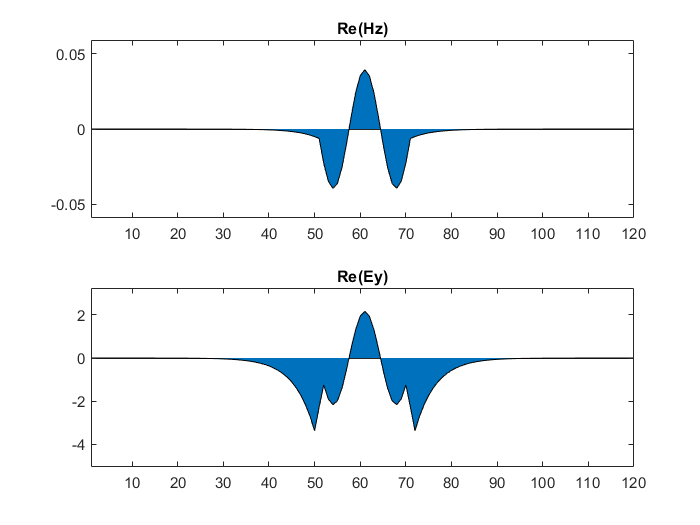

Mode number: 3
kx : 0.268
Error of calculation: 0.000
Power: 1.000


% get the eigenmode from matlab
% eps_cut = [ones(1, 20),5*ones(1,20), 3*ones(1, 20), 1*ones(1, 20)];
eps_cut = [ones(1,50), 12.25*ones(1,20), ones(1, 50)];
% eps_cut = [1:40, 40:1];
eps = repmat(eps_cut, 1000, 1); % struct the simulated region
c = 3 * 10^8;
omega = 0.15 * c;

% set the input here
[input.Ey, input.Hz, input.k] = wave_mode(eps_cut, omega, 3, 'pos'); 

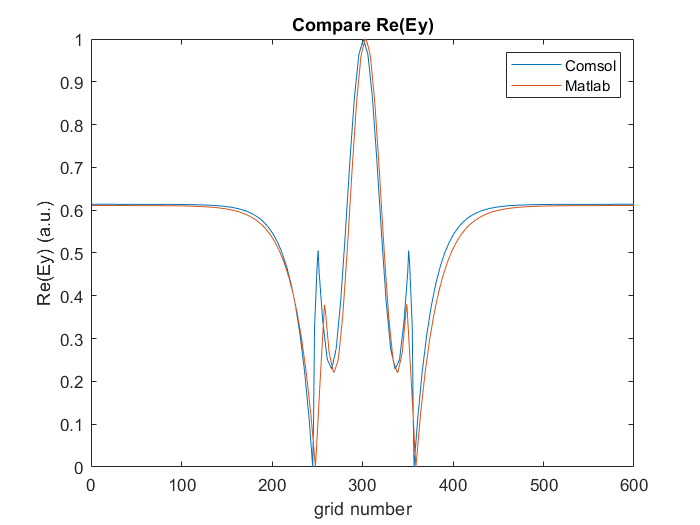

num = size(A, 2);
Ey_m = interp1(input.Ey, linspace(1, length(input.Ey), num));
Ey_m = normalize(Ey_m, "range");
Ey_c = normalize(A(2, :), "range");

figure()
hold on
plot(Ey_c);
plot(Ey_m);
hold off

legend('Comsol', 'Matlab');
xlim([0,600]);
box on
title('Compare Re(Ey)')
xlabel('grid number')
ylabel('Re(Ey) (a.u.)')